%syms M m1 m2 l1 l2 g

M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

## A_f and B_f matrices

A_f =[0 1 0 0 0 0;0 0 (-m1*g)/M 0 (-m2*g)/M 0;0 0 0 1 0 0;0 0 -(g/l1)*((m1+M)/M) 0 (-m2*g)/M*l1 0;0 0 0 0 0 1;0 0 (-m1*g)/M*l2 0 -(g/l2)*((m2+M)/M) 0]

A_f =          0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0    1.0000         0         0
         0         0   -0.5396         0  -19.6200         0
         0         0         0         0         0    1.0000
         0         0   -9.8100         0   -1.0791         0


B_f =[0;1/M;0;1/(M*l1);0;1/(M*l2)]

B_f = 	1.0e+-3 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


C = [1,0,0,0,0,0]

C =      1     0     0     0     0     0


D = [0]

D = 0


eigs(A_f);

plant = ss(A_f,B_f,C,D)


plant =
 
  A = 
            x1       x2       x3       x4       x5       x6
   x1        0        1        0        0        0        0
   x2        0        0   -0.981        0   -0.981        0
   x3        0        0        0        1        0        0
   x4        0        0  -0.5396        0   -19.62        0
   x5        0        0        0        0        0        1
   x6        0        0    -9.81        0   -1.079        0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Plant_poles = pole(plant)

Plant_poles =    0.0000 + 0.0000i
   0.0000 + 0.0000i
  -3.6148 + 0.0000i
  -0.0000 + 3.8322i
  -0.0000 - 3.8322i
   3.6148 + 0.0000i


## Controllability Matrix and rank condition

Co = ctrb(plant)

Co =          0    0.0010         0   -0.0001         0    0.0025
    0.0010         0   -0.0001         0    0.0025         0
         0    0.0001         0   -0.0020         0    0.0128
    0.0001         0   -0.0020         0    0.0128         0
         0    0.0001         0   -0.0006         0    0.0202
    0.0001         0   -0.0006         0    0.0202         0


Ob = obsv(plant)

Ob =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0   -0.9810         0   -0.9810
         0         0   10.1529         0   20.3058         0
         0         0         0   10.1529         0   20.3058


rank_Co = rank(Co)

rank_Co = 6

rank_Ob = rank(Ob)

rank_Ob = 6

## Position of poles

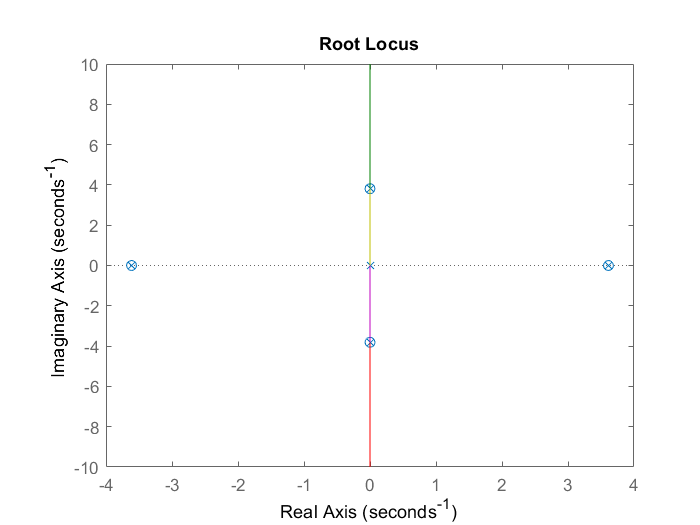

rlocus(plant)

## Initial conditions

I = [0;0;0;0;0;0];

## LQR Controller Design

Q = [1200000000000 10 0 0 0 0;10 2 0 0 0 0;0 0 11000000000000 0 0 0 ; 0 0 0 0.1 0 0;0 0 0 0 14000000000000 0;0 0 0 0 0 1];
R = 10;
eig_Q = eigs(Q);
N = [1;2;3;1;5;2];

Positive_Semi_Definite = [Q N;N' R] %this matrix must be positive-semi definite

Positive_Semi_Definite = 	1.0e+13 *

    0.1200    0.0000         0         0         0         0    0.0000
    0.0000    0.0000         0         0         0         0    0.0000
         0         0    1.1000         0         0         0    0.0000
         0         0         0    0.0000         0         0    0.0000
         0         0         0         0    1.4000         0    0.0000
         0         0         0         0         0    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


[K2,S2,e2] = lqr(A_f+eye(size(A_f)),B_f,Q,R,N)

K2 = 	1.0e+07 *

   -0.0763   -0.0589   -2.8052   -0.6839    3.0355    0.9735


S2 = 	1.0e+15 *

    0.0023    0.0011    0.0360    0.0081   -0.0442   -0.0150
    0.0011    0.0006    0.0226    0.0048   -0.0245   -0.0089
    0.0360    0.0226    0.8753    0.1910   -0.9032   -0.3241
    0.0081    0.0048    0.1910    0.0429   -0.2012   -0.0703
   -0.0442   -0.0245   -0.9032   -0.2012    1.0050    0.3488
   -0.0150   -0.0089   -0.3241   -0.0703    0.3488    0.1250


e2 =  -13.5859 +13.6057i
 -13.5859 -13.6057i
  -4.5397 + 0.0000i
  -1.1921 + 3.6421i
  -1.1921 - 3.6421i
  -2.6311 + 0.0000i


## Root Locus with LQR Controller

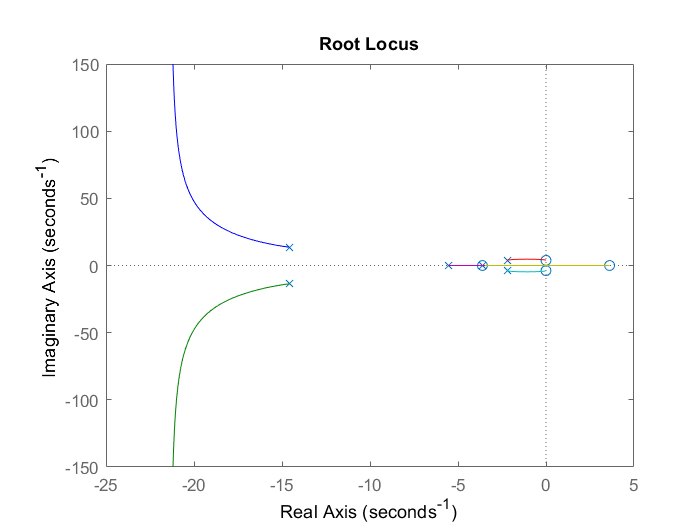

rlocus(Plant_LQR)

A_cl = A_f-(B_f*K2);
Plant_LQR = ss(A_cl,B_f,C,D)


Plant_LQR =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2       762.8       588.8   2.805e+04        6839  -3.036e+04       -9735
   x3           0           0           0           1           0           0
   x4       38.14       29.44        1402         342       -1537      -486.7
   x5           0           0           0           0           0           1
   x6       76.28       58.88        2795       683.9       -3037      -973.5
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



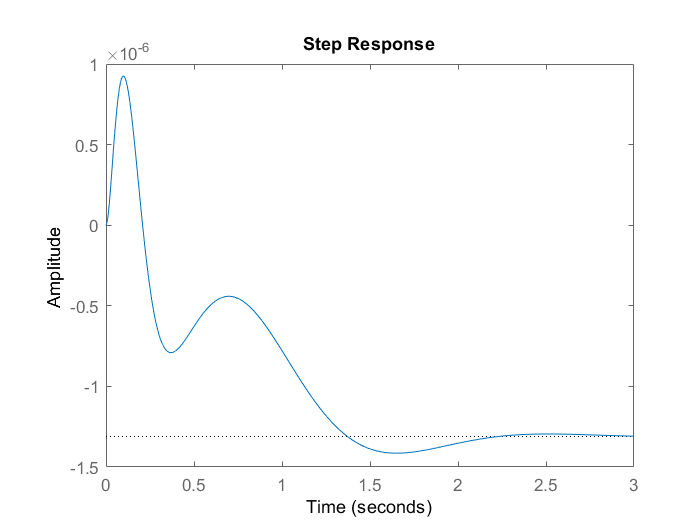

step(Plant_LQR)

## Luenberger Observer Design 

%Desired Location of Poles

Poles_L_Obs = [-28;-30;-10;-6;-2;-4];
L = place(A_f',C',Poles_L_Obs)'

L = 	1.0e+05 *

    0.0008
    0.0228
   -0.9791
   -3.8919
    0.6901
    2.2299



Luen_SYS = ss(A_f-L*C,B_f,C,D)


Luen_SYS =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1         -80           1           0           0           0           0
   x2       -2278           0      -0.981           0      -0.981           0
   x3   9.791e+04           0           0           1           0           0
   x4   3.892e+05           0     -0.5396           0      -19.62           0
   x5  -6.901e+04           0           0           0           0           1
   x6   -2.23e+05           0       -9.81           0      -1.079           0
 
  B = 
           u1
   x1       0
   x2   0.001
   x3       0
   x4   5e-05
   x5       0
   x6  0.0001
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



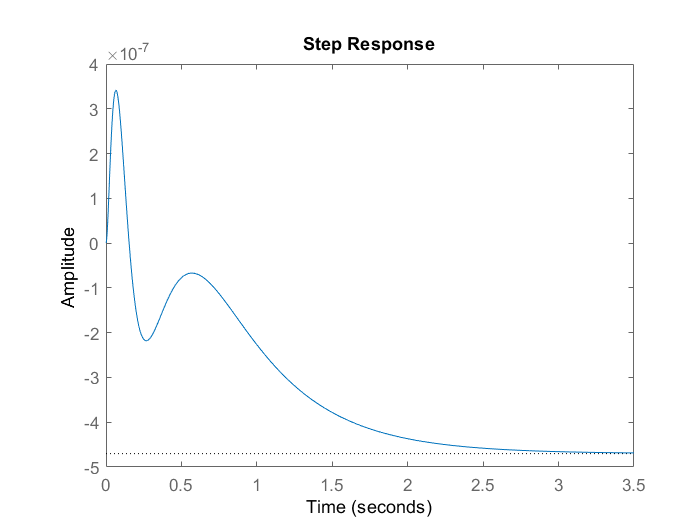

step(Luen_SYS)

## Check for obervability

C_Lo = ctrb(A_f',C')

C_Lo =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0   -0.9810         0   10.1529         0
         0         0         0   -0.9810         0   10.1529
         0         0   -0.9810         0   20.3058         0
         0         0         0   -0.9810         0   20.3058


rank(C_Lo)

ans = 6

Ob_Lo = obsv(A_f,C)

Ob_Lo =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0   -0.9810         0   -0.9810         0
         0         0         0   -0.9810         0   -0.9810
         0         0   10.1529         0   20.3058         0
         0         0         0   10.1529         0   20.3058


rank(Ob_Lo)

ans = 6

## LQG Controller Design

At = [ A_f-B_f*K2             B_f*K2
       zeros(size(A_f))    A_f-L*C ];

Bt = [    B_f
       zeros(size(B_f)) ];

Ct = [ C    zeros(size(C)) ];

## LQG Step Response

step(ss(At,Bt,Ct,0))